# Turotial: EPI Distortion Correction

# Part 2: Dynamic Distortion Correction = using EPI-derived series of field maps

## Computational Steps Overview:

- Defining inputs

- Calculating phase offset from GEFM reference and EPI phase data

- Phase offset removal and Voxel Shift Map calculation from EPI phase

- Unwarping 

- Quality assurance

## Step 1 - Defining inputs

working_dir = '/home/bdymerska/Documents/data/7T/2022/20221130.M700466_FIL/tutorial/data_mc_share_copy' ;
cd(working_dir)

Let's have a look at the available data.

**Field map data:** magnitude and phase difference (4 mm isotropic) from dual-echo GRE scan (GEFM)

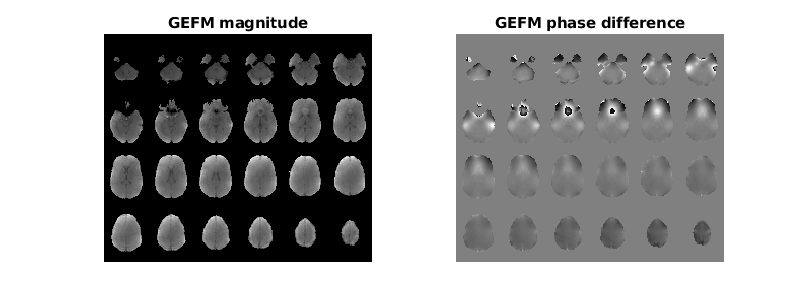

GEFM_mag = nifti('GEFM_mag.nii').dat(:,:,:) ;
GEFM_phdiff = nifti('GEFM_ph.nii').dat(:,:,:) ;

figure('Position', [0 0 1200 400]);
subplot 121 
montage(mat2gray(permute(GEFM_mag(:,25:48,:),[1 3 4 2])))
title('GEFM magnitude')
subplot 122 
montage(mat2gray(permute(GEFM_phdiff(:,25:48,:),[1 3 4 2])))
title('GEFM phase difference')

**EPI data:** multi-volume **magnitude and phase data** (0.8 mm isotropic) from EPI run:

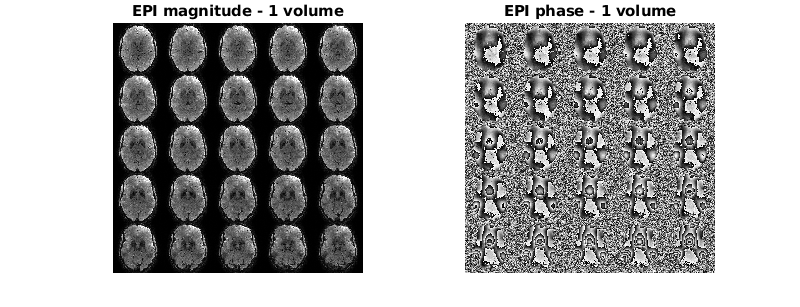

vol_nr = 50 ;
EPI_mag = nifti(fullfile(working_dir,'EPI','mag','mag.nii')).dat(:,:,:,vol_nr) ;
EPI_ph = nifti(fullfile(working_dir,'EPI','ph','ph.nii')).dat(:,:,:,vol_nr) ;

figure('Position', [0 0 1200 400]);
subplot 121 
montage(mat2gray(permute(EPI_mag(:,:,26:end-38),[2 1 4 3]),[0 1000]));
title('EPI magnitude - 1 volume');
subplot 122
montage(mat2gray(permute(EPI_ph(:,:,26:end-38),[2 1 4 3])));
title('EPI phase - 1 volume');

## Step 2 - Calculating phase offset from GEFM reference and EPI phase data

We will do:

    A. GEFM Calculation 

    B. EPI Phase Unwrapping

    C. Phase Offset Calculation and Extrapolation

### A. GEFM Calculation and extrapolation

As in EPI_DistortionCorrection_Tutorial we choose ROMEO [3] for GEFM calculation:

system('romeo -p GEFM_ph.nii -m GEFM_mag.nii -o GEFM_ph_unwr.nii -t 3.06 -B');
GEFM = nifti('B0.nii').dat(:,:,:);
GEFM_extrap = GEFM;
GEFM_extrap(GEFM_extrap==0) = NaN;
GEFM_extrap = smoothn(GEFM_extrap, 1, 'MaxIter',300);

createNifti(GEFM_extrap, 'GEFM_B0_extrap.nii', nifti('GEFM_ph.nii').mat)

### B. GEFM Corregistration to EPI space

Corregister GEFM to the closest (in time) EPI volume.

For this dataset GEFM was acquired AFTER the EPI run so we take last volume. 

coreg_GEFM2EPI(sprintf('EPI/mag/mag_%02.f.nii',vol_nr), 'GEFM_mag.nii', 'GEFM_B0_extrap.nii');

Initialising batch system... Duplicate application tag in applications 'SPM' and 'SPM'.
Duplicate application tag in applications 'BasicIO' and 'BasicIO'.
done.


------------------------------------------------------------------------
24-May-2023 12:12:28 - Running job #1
------------------------------------------------------------------------
24-May-2023 12:12:28 - Running 'Coregister: Estimate & Reslice'

SPM12: spm_coreg (v7320)                           12:12:28 - 24/05/2023
Completed                               :          12:12:44 - 24/05/2023

SPM12: spm_reslice (v7141)                         12:12:44 - 24/05/2023
Completed                               :          12:12:45 - 24/05/2023
24-May-2023 12:12:45 - Done    'Coregister: Estimate & Reslice'
24-May-2023 12:12:45 - Done



### C. EPI Phase Unwrapping 

system(sprintf('romeo -p EPI/ph/ph.nii -m EPI/mag/mag.nii -o EPI/ph/ph_unwr.nii -t epi -k nomask -q -g --template %i -v',vol_nr))

Phase loaded!
Mag loaded!
Echoes are 1:50
TEs are [1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0, 1.0]
individual unwrapping is false
echo 50 used as template
perform unwrapping...
unwrapping finished!
Calculate and write quality map...


ans = 0

-k nomask option in ROMEO unwrapps everything including background noise, we will apply masking later on

-q option saves quality map, which guides ROMEO unwrapping process, but can be also used as a mask if threshodled and binarized

In case EPI phase is corrupted by open-ended fringe line artifacts, phase uwnrapping should be performed after phase offset subtraction (Step 2.D) rather than before it to remove these artifacts.

Let's have a look at the quality of EPI phase uwnrapping.

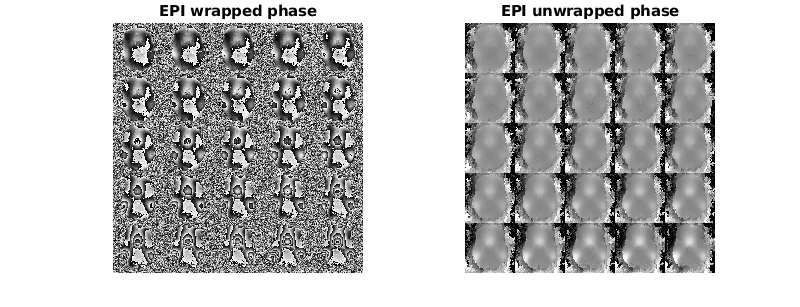

vol_nr = 50 ;
EPI_ph_unwr = nifti(fullfile(working_dir,'EPI','ph','ph_unwr.nii')).dat(:,:,:,vol_nr) ;
figure('Position', [0 0 1200 400]);
subplot 121 
montage(mat2gray(permute(EPI_ph(:,:,26:end-38),[2 1 4 3])));
title('EPI wrapped phase');
subplot 122
montage(mat2gray(permute(EPI_ph_unwr(:,:,26:end-38),[2 1 4 3]),[-30 30]));
title('EPI unwrapped phase');

### D. Phase Offset Estimation and Extrapolation

Depending on the type of image reconstruction (e.g. SENSE, GRAPPA + some coil combination), a different phase offset may be present in EPI phase.

Here we will assume the difference in GEFM and a field map from the closest (in time) EPI volume is negligible.

Phase offset (p0) will be estimated as a phase difference between EPI phase and scaled GEFM:


$$\varphi_0^{\textrm{fMRI}} =\varphi_{\left(\textrm{tp}=1\right)}^{\textrm{fMRI}} -2\pi \cdot \textrm{TE}\cdot {\Delta B}_0^{\textrm{ref}}$$


vol_nr = 50;
TE_epi = 17.7e-3 ; % EPI echo time in seconds
interp_method = -5 ; % 1 is trilinear, values > 0 are nth order polnomial, values < 0 are nth order sinc ...
EPI_ph_unwr = nifti(fullfile(working_dir,'EPI','ph','ph_unwr.nii')).dat(:,:,:,vol_nr) ;

GEFM_file = 'coreg2EPI_GEFM_B0_extrap.nii' ;
% GEFM = nifti(GEFM_file).dat(:,:,:) ;
%%%%%%
VSM_SDC_file = 'coreg2EPI_VSM_SDC.nii';
VSM_SDC = nifti(VSM_SDC_file).dat(:,:,:);
EPI_ph_file = fullfile(working_dir,'EPI','ph','ph_unwr.nii');


EPI_mat = nifti(EPI_ph_file).mat ;
[Mx, My, Mz] = size(nifti(EPI_ph_file).dat(:,:,:,1)); % reading matrix size of the EPI
[x,y,z] = ndgrid(1:Mx,1:My,1:Mz); % creating rectangular grid for 3D space
% warp field initialisation:
F_warp_init = [x(:) y(:) z(:)]; 
F_warp = F_warp_init;
F_warp(:,2) = F_warp_init(:,2) + reshape(-VSM_SDC,[Mx*My*Mz,1]);
GEFM_warped = reshape(spm_sample_vol(spm_vol(GEFM_file),...
        F_warp(:,1),F_warp(:,2),F_warp(:,3),interp_method),[Mx,My,Mz]);
% GEFM_file = 'coreg2EPI_GEFM_B0_extrap_warped.nii';
% createNifti(GEFM_warped,VSM_SDC_file, EPI_mat)

p0 = EPI_ph_unwr - 2*pi*TE_epi*GEFM_warped ;


% p0 = EPI_ph_unwr - 2*pi*TE_epi*GEFM ;
% createNifti(p0, 'p0.nii',nifti(fullfile(working_dir,'EPI','ph','ph.nii')).mat)

How does our phase offset look like?

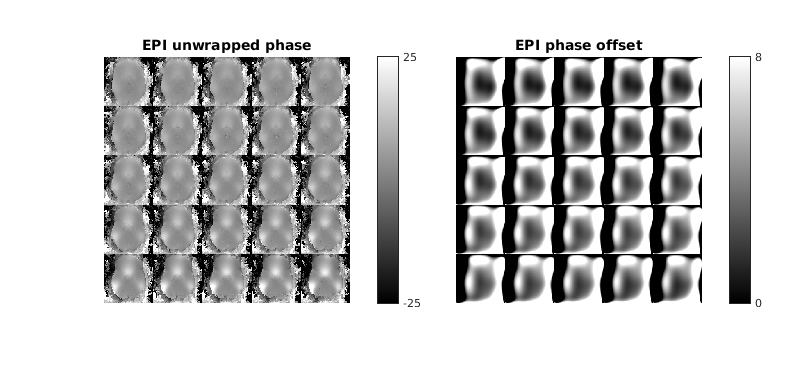

EPI_ph_unwr = nifti(fullfile(working_dir,'EPI','ph','ph_unwr.nii')).dat(:,:,:,vol_nr) ;
figure('Position', [0 0 1200 400]);
subplot 121 
montage(mat2gray(permute(EPI_ph_unwr(:,:,26:end-38),[2 1 4 3]),[-25 25]));
ax = gca;
ax.Position(3) = 1.2*ax.Position(3);
colorbar('Ticks',[0 1],'TickLabels',{-25, 25});
title('EPI unwrapped phase');
subplot 122
montage(mat2gray(permute(p0(:,:,26:end-38),[2 1 4 3]),[0 8]));
ax = gca;
ax.Position(3) = 1.2*ax.Position(3);
colorbar('Ticks',[0 1],'TickLabels',{0, 8});
title('EPI phase offset');

The visible brain structure in the phase offset comes most probably from the resolution difference between GEFM data (4 mm isotropic) and EPI data (0.8 mm isotropic). It can also come from difference in GEFM and EPI field map, which we assumed was small. These differences we won't be able to unwrap in this case, but we will be able to unwrap any dynamic changes happening between EPI volumes.

To minimize noise amplification and to remove residual structural information from the phase offset $\varphi_0^{\textrm{fMRI}}$ we will smooth and extrapolate it:

qmask = nifti(fullfile(working_dir,'EPI','ph','quality.nii')).dat(:,:,:) ;
qmask = imbinarize(qmask,0.3);
qmask = imfill(qmask,8,'holes') ;
% qmask(qmask<0) = 0;
% qmask(~isfinite(qmask))=0;
p0=p0.*qmask;
p0(~isfinite(p0))=0;
%%% reformating 3D data into 3 independent and one dependent variable vectors: 
% omitting zeros
[x_nonzero,y_nonzero,z_nonzero, p0_nonzero_vector] = find3(p0) ;
% [x,y,z] = ndgrid(1:Mx,1:My,1:Mz); % creating rectangular grid for 3D space
% with zeros (for final result with extrapolated values outside the brain)
[x, y, z, ~] = find3(ones(Mx,My,Mz)) ;

% fitting polynomial
p = polyfitn([x_nonzero,y_nonzero,z_nonzero],p0_nonzero_vector, 7) ;
p0_fit_vector = polyvaln(p, [x,y,z]) ;
p0 = reshape(p0_fit_vector, [Mx My Mz]) ;


% % p0 = angle(gadgetron.FIL.utils.mysmooth(exp(1i*p0),6,[0 0 0]));
% % % p0(qmask==0) = NaN ;
% % % p0 = smoothn(p0,qmask, 5, 'robust');
% createNifti(p0_fit, 'p0_polyfit5.nii',nifti(fullfile(working_dir,'EPI','ph','ph.nii')).mat)

A tip: In this particular case the phase offset has no large wraps or open-ended fringe lines. This doesn't have to be the case. If we plan to do phase uwnrapping after phase offset subtraction we need to preserve 2$\pi$ differences at wrap boundaries, which are then detected by an unwrapping algotrithm. We can do it by complex-domain smoothing:

% p0_imag = imag(exp(1i*p0)) ;
% p0_real = real(exp(1i*p0)) ;
% p0_imag = smoothn(p0_imag, 4) ;
% p0_real = smoothn(p0_real, 4) ;
% p0 = angle(p0_real + 1i*p0_imag) ;

### D. EPI: Phase offset removal, Voxel Shift Map calculation and dynamic distortion correction

Phase offset, $\varphi_0^{\textrm{fMRI}}$, should not change subtantially during the fMRI run, which means we can subtract it from each volume of EPI phase to create a series of EPI-based field maps capturing dynamic changes in the field:


$${\Delta B}_0^{\textrm{fMRI}} \left(\textrm{tp}\right)=\frac{\varphi_{\left(\textrm{tp}\right)}^{\textrm{fMRI}} -\varphi_0^{\textrm{fMRI}} }{2\pi \cdot \textrm{TE}}$$


Similarily as in Part 1 of the tutorial, the relationship between Voxel Shift Map (VSM) and a Field Map is as following:


$${\textrm{VSM}}^{\textrm{fMRI}} \left(\textrm{tp}\right)=\frac{{\Delta B}_0^{\textrm{fMRI}} \left(\textrm{tp}\right)\cdot M_{\textrm{PE}} \cdot t_{\textrm{esp}} }{R}\;\left\lbrack \textrm{voxels}\right\rbrack$$


where:

$M_{\textrm{PE}}$ - Matrix size in PE direction

$t_{\textrm{esp}}$   - Echo spacing time, e.g. for trapezoid gradient form: 1 x flat top time + 2 x ramp up time

$R$     - Acceleration in PE direction

Above steps, together with unwarping can be written in a single loop:

EPI_ph_file = fullfile(working_dir,'EPI','ph','ph_unwr.nii');
vol_nr = 50 ;
% EPI_mask_thr = 80;
% parameters for VSM creation:
M_PE = 240;
t_esp = (800 +2*210)*1e-6; % in seconds
R = 2*4; % this EPI was acquired with 2 in-plane segments and 4-fold undersampling

% preparation for intensity shifting and interpolation
interp_method = -5 ; % 1 is trilinear, values > 0 are nth order polnomial, values < 0 are nth order sinc ...

EPI_mat = nifti(EPI_ph_file).mat ;
[Mx, My, Mz] = size(nifti(EPI_ph_file).dat(:,:,:,1)); % reading matrix size of the EPI
[x,y,z] = ndgrid(1:Mx,1:My,1:Mz); % creating rectangular grid for 3D space
% warp field initialisation:
F_warp_init = [x(:) y(:) z(:)]; 

EPI_DDC = zeros(Mx,My,Mz);
for t = vol_nr
    % creation of mask for each EPI volume
%     EPI_file = fullfile('EPI/mag',sprintf('mag_%02.f.nii',t)) ;
%     EPI_mask = nifti(EPI_file).dat(:,:,:);
%     EPI_mask = imbinarize(EPI_mask,EPI_mask_thr);
    
    
    % subtraction of phase offset from EPI phase:
    EPI_ph_unwr = nifti(EPI_ph_file).dat(:,:,:,t) ;
    EPI_FM = (EPI_ph_unwr - p0)/(2*pi*TE_epi) ;
    
    % Voxel Shift Map calculation:
    VSM = EPI_FM*M_PE*t_esp/R ;
%     VSM(EPI_mask ==0) = NaN ;
    VSM = smoothn(VSM, 2,'robust') ; % moderate smoothing to avoid noise propagation
    VSM_file = sprintf('VSM_DDC_%02.f.nii',t);
    createNifti(VSM, VSM_file, EPI_mat)

    % calculating warp field:
    F_warp = F_warp_init;
    F_warp(:,2) = F_warp_init(:,2) + reshape(VSM,[Mx*My*Mz,1]);

    % calculating Jacobian determinant:
%     VSM = reshape(spm_sample_vol(spm_vol(VSM_file),...
%         F_warp(:,1),F_warp(:,2),F_warp(:,3),interp_method),[Mx,My,Mz]);
    VSM_grad = (circshift(VSM,1,2)-circshift(VSM,-1,2))/2 ;
    VSM_grad(~isfinite(VSM_grad))=0;
    J_field = 1 + VSM_grad ;

    % application of warp field and interpolation
    EPI_file = fullfile('EPI/mag',sprintf('mag_%02.f.nii',t)) ;
    fprintf('Unwarping %s \n', EPI_file)

    EPI_DDC = reshape(spm_sample_vol(spm_vol(EPI_file),...
        F_warp(:,1),F_warp(:,2),F_warp(:,3),interp_method),[Mx,My,Mz]);
    EPI_DDC_file = fullfile('EPI/mag',sprintf('mag_%02.f_ddc.nii',t)) ;
    createNifti(EPI_DDC, EPI_DDC_file, EPI_mat)

    % optional Jacobian intensity modulation:
    EPI_DDC_jac = EPI_DDC.*J_field ;
    EPI_DDC_file = fullfile('EPI/mag',sprintf('mag_%02.f_ddc_jac.nii',t)) ;
    createNifti(EPI_DDC_jac, EPI_DDC_file, EPI_mat)
    

end

Unwarping EPI/mag/mag_50.nii 


## Step 5 - Quality Assurance

Qualitative and quantitative analysis of the quality of distortion correction is desirable. 

Examples possible QA procedures:

- Visual comparison of reference structural acan, original, and corrected data.

- Dice coefficient for grey matter masks.

- tSNR 

#### Visual inspection:

vol_nr = 50 ;
slice = 43 ;

EPI_1vol = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f.nii',vol_nr))).dat(:,:,:) ;
EPI_1vol_DDC = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f_ddc.nii',vol_nr))).dat(:,:,:) ;
EPI_1vol_DDC_jac = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f_ddc_jac.nii',vol_nr))).dat(:,:,:) ;

EPI_noDC_DDC = cat(3, EPI_1vol(:,:,slice), EPI_1vol_DDC(:,:,slice)) ;
EPI_noDC_DDC = repmat(EPI_noDC_DDC, [1 1 10]);
implay(mat2gray(imrotate(EPI_noDC_DDC,-90),[0 1000]), 1)

EPI_DDC_DDCjac = cat(3, EPI_1vol_DDC(:,:,slice), EPI_1vol_DDC_jac(:,:,slice)) ;
EPI_DDC_DDCjac = repmat(EPI_DDC_DDCjac, [1 1 10]);
implay(mat2gray(imrotate(EPI_DDC_DDCjac,-90),[0 1000]), 1)

How do we know if we minimized/removed geometric distortions?

Good examples of quality assurance can be found in Ref. [6]:

We can for instance calculate Dice coefficient between Gray Matter (GM) mask from structural reference and EPI.

Let's have a look at MP2RAGE and EPI together:

vol_nr = 50 ;
slice = 43 ;

EPI_1vol = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f.nii',vol_nr))).dat(:,:,:) ;
MP2RAGE = nifti(fullfile(working_dir, 'coreg2EPI_mp2rage.nii')).dat(:,:,:);
MP2RAGE(~isfinite(MP2RAGE))=0;
EPI_DDC_MP2RAGE = cat(3, mat2gray(EPI_1vol(:,:,slice),[0 1000]), mat2gray(MP2RAGE(:,:,slice),[0 4100])) ;
EPI_DDC_MP2RAGE = repmat(EPI_DDC_MP2RAGE, [1 1 10]);
implay(imrotate(EPI_DDC_MP2RAGE,-90), 1)

vol_nr = 50 ;
slice = 43 ;

EPI_1vol_DDC = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f_ddc.nii',vol_nr))).dat(:,:,:) ;
MP2RAGE = nifti(fullfile(working_dir, 'coreg2EPI_mp2rage.nii')).dat(:,:,:);
MP2RAGE(~isfinite(MP2RAGE))=0;
EPI_DDC_MP2RAGE = cat(3, mat2gray(EPI_1vol_DDC(:,:,slice),[0 1000]), mat2gray(MP2RAGE(:,:,slice),[0 4100])) ;
EPI_DDC_MP2RAGE = repmat(EPI_DDC_MP2RAGE, [1 1 10]);
implay(imrotate(EPI_DDC_MP2RAGE,-90), 1)

#### Dice Coefficient

Let's load precalculated Gray Matter (GM) probability maps (SPM12 Segment tool) for MP2RAGE and EPIs, threshold them and calculate pair-wise Dice Coefficients:

vol_nr = 50;
slice = 43 ;
GM_threshold = 0.5 ;

% loading precalculated GM probability maps:
MP2RAGE_GM = nifti(fullfile(working_dir,'coreg2EPI_mp2rage_GM.nii')).dat(:,:,slice);
EPI_GM = nifti(fullfile(working_dir,'EPI/mag',sprintf('c1mag_%02.f.nii',vol_nr))).dat(:,:,slice) ;
EPI_DDC_GM = nifti(fullfile(working_dir,'EPI/mag',sprintf('c1mag_%02.f_ddc.nii',vol_nr))).dat(:,:,slice) ;
EPI_DDCjac_GM = nifti(fullfile(working_dir,'EPI/mag',sprintf('c1mag_%02.f_ddc_jac.nii',vol_nr))).dat(:,:,slice) ;

% creating GM masks:
MP2RAGE_GM = imbinarize(MP2RAGE_GM, GM_threshold);
EPI_GM = imbinarize(EPI_GM, GM_threshold);
EPI_DDC_GM = imbinarize(EPI_DDC_GM, GM_threshold);
EPI_DDCjac_GM = imbinarize(EPI_DDCjac_GM, GM_threshold);

% calculating pair-wise Dice Coefficients:
MP2RAGE_EPI_dice = dice(MP2RAGE_GM, EPI_GM)

MP2RAGE_EPI_dice = 0.7063

MP2RAGE_EPI_DDC_dice = dice(MP2RAGE_GM, EPI_DDC_GM)

MP2RAGE_EPI_DDC_dice = 0.6875

MP2RAGE_EPI_DDCjac_dice = dice(MP2RAGE_GM, EPI_DDCjac_GM)

MP2RAGE_EPI_DDCjac_dice = 0.7155

## References:

[1] Jenkinson, Mark. "Fast, automated, N‐dimensional phase‐unwrapping algorithm." *Magnetic Resonance in Medicine: An Official Journal of the International Society for Magnetic Resonance in Medicine* 49.1 (2003): 193-197.

[2] Abdul-Rahman, Hussein S., et al. "Fast and robust three-dimensional best path phase unwrapping algorithm." *Applied optics* 46.26 (2007): 6623-6635.

[3] Dymerska, Barbara, and Eckstein, Korbinian, et al. "Phase unwrapping with a rapid opensource minimum spanning tree algorithm (ROMEO)." *Magnetic resonance in medicine* 85.4 (2021): 2294-2308.

[https://github.com/korbinian90/ROMEO](https://github.com/korbinian90/ROMEO)

[4] [https://uk.mathworks.com/matlabcentral/fileexchange/25634-smoothn](https://uk.mathworks.com/matlabcentral/fileexchange/25634-smoothn)

[5] [https://github.com/spm/](https://github.com/spm/)

[6] Malekian et al, 

[https://github.com/fil-physics/Publication-Code/tree/master/3DEPI-DistortionCorrection](https://github.com/fil-physics/Publication-Code/tree/master/3DEPI-DistortionCorrection)

## Acknowledgements

The Wellcome Centre for Human Neuroimaging is supported by core funding from the Wellcome [203147/Z/16/Z].

Many thanks to Prof. Eleanor Maguire and her student Yan Wu for sharing their 7T MRI data from project funded by a Wellcome Principal Research Fellowship to E. Maguire (grant reference: 210567/Z/18/Z).